Load the data from a saved material (created during the experimental process)

data = load("run1_heating.mat");
data = data.data;

Plot the data

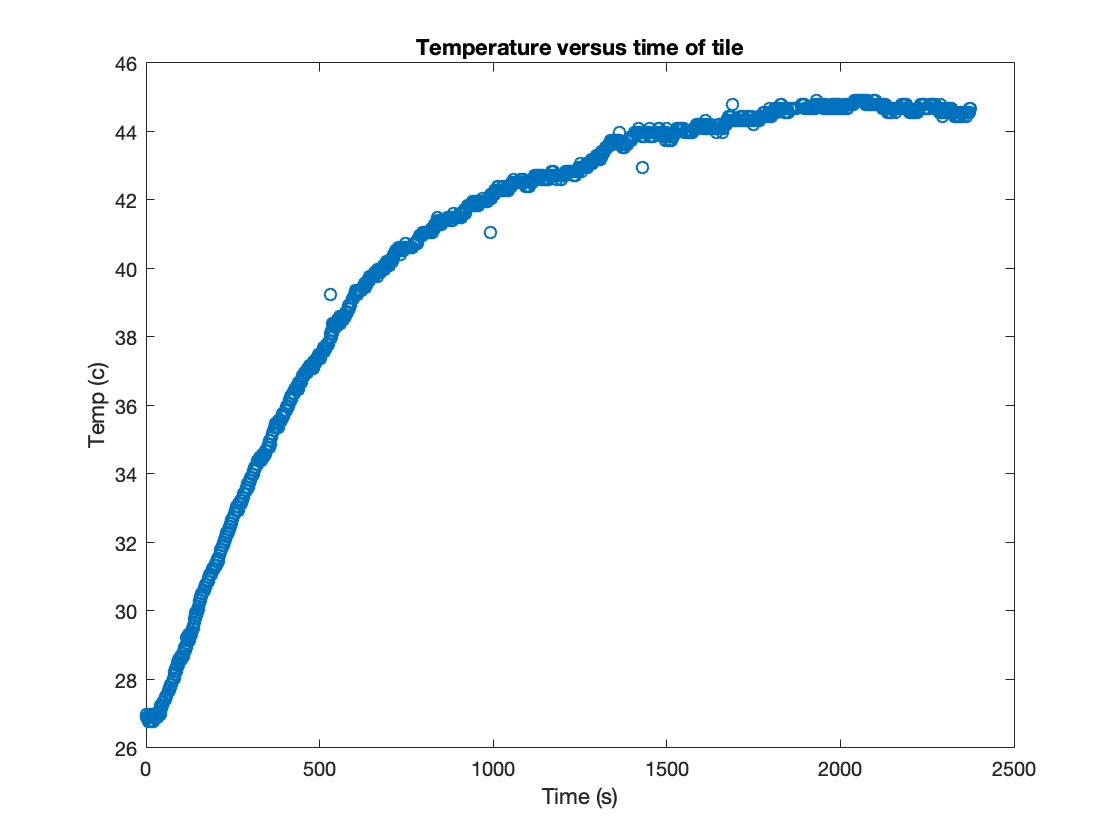

time = nonzeros(data(:,1));
temp = nonzeros(data(:,2));
plot(time,temp, "o")
title("Temperature versus time of tile")
xlabel("Time (s)")
ylabel("Temp (c)")
saveas(gcf,'experiment-plot.png')

Find the specific heat

q = 5 % W

q = 5

m = 1 % g

m = 1

temp(end)

ans = 44.6798

temp(1)

ans = 26.8767

dt = temp(end)-temp(1) % c

dt = 17.8032

cp = q/m*dt % does this actually make sense?

cp = 89.0158